clear
clc
run RRpendulum_kinctrl_numericalsetup.mlx

$$DH\_table = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & 0 & q_{1}\left(t\right)\\ \frac{\pi }{2} & 0 & r & q_{2}\left(t\right) \end{array}\right)$$

$$o2Pm = \left(\begin{array}{c} 0\\ 0\\ -l\\ 1 \end{array}\right)$$

$$o0Pm = \left(\begin{array}{c} -r\,\sin\left(q_{1}\left(t\right)\right)-l\,\cos\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\\ r\,\cos\left(q_{1}\left(t\right)\right)-l\,\sin\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\\ -l\,\cos\left(q_{2}\left(t\right)\right)\\ 1 \end{array}\right)$$

$$jac\_m = \left(\begin{array}{cc} l\,\sin\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)-r\,\cos\left(q_{1}\left(t\right)\right) & -l\,\cos\left(q_{1}\left(t\right)\right)\,\cos\left(q_{2}\left(t\right)\right)\\ -r\,\sin\left(q_{1}\left(t\right)\right)-l\,\cos\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right) & -l\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{1}\left(t\right)\right)\\ 0 & l\,\sin\left(q_{2}\left(t\right)\right) \end{array}\right)$$

$$Ekin = \begin{array}{l} \frac{{\mathrm{Iz}}_{1}\,\sigma_{1}}{2}+\frac{l^{2}\,m\,\sigma_{1}}{2}+\frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}{2}+\frac{m\,r^{2}\,\sigma_{1}}{2}-\frac{l^{2}\,m\,{\cos\left(q_{2}\left(t\right)\right)}^{2}\,\sigma_{1}}{2}+l\,m\,r\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2} \end{array}$$

$$Epot = -g\,l\,m\,\cos\left(q_{2}\left(t\right)\right)$$

$$L = \begin{array}{l} \frac{{\mathrm{Iz}}_{1}\,\sigma_{1}}{2}+\frac{l^{2}\,m\,\sigma_{1}}{2}+\frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}{2}+\frac{m\,r^{2}\,\sigma_{1}}{2}-\frac{l^{2}\,m\,{\cos\left(q_{2}\left(t\right)\right)}^{2}\,\sigma_{1}}{2}+g\,l\,m\,\cos\left(q_{2}\left(t\right)\right)+l\,m\,r\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2} \end{array}$$

$$Q = \left(\begin{array}{c} \tau_{1}-b_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ -b_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}\right)$$

$$tau = \left(\begin{array}{c} \tau_{1}\\ 0 \end{array}\right)$$

$$EOM = \begin{array}{l} \left(\begin{array}{c} -m\,l^{2}\,{\cos\left(q_{2}\left(t\right)\right)}^{2}\,\sigma_{1}+m\,l^{2}\,\sigma_{1}+m\,l\,r\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{2}+m\,r^{2}\,\sigma_{1}+{\mathrm{Iz}}_{1}\,\sigma_{1}-m\,\sin\left(q_{2}\left(t\right)\right)\,l\,r\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+m\,\sin\left(2\,q_{2}\left(t\right)\right)\,l^{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+b_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)-\tau_{1}\\ m\,l^{2}\,\sigma_{2}+m\,r\,\cos\left(q_{2}\left(t\right)\right)\,l\,\sigma_{1}-m\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\,l^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+b_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)+g\,m\,\sin\left(q_{2}\left(t\right)\right)\,l \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right) \end{array}$$

$$solve\_EOM = \left(\begin{array}{c} m\,v_{1}\,\sin\left(2\,q_{2}\right)\,l^{2}\,v_{2}-m\,{\dot{v}}_{1}\,l^{2}\,{\cos\left(q_{2}\right)}^{2}+m\,{\dot{v}}_{1}\,l^{2}-m\,\sin\left(q_{2}\right)\,l\,r\,{v_{2}}^{2}+m\,{\dot{v}}_{2}\,l\,r\,\cos\left(q_{2}\right)+m\,{\dot{v}}_{1}\,r^{2}-\tau_{1}+{\mathrm{Iz}}_{1}\,{\dot{v}}_{1}+b_{1}\,v_{1}=0\\ b_{2}\,v_{2}+l^{2}\,m\,{\dot{v}}_{2}+g\,l\,m\,\sin\left(q_{2}\right)-l^{2}\,m\,{v_{1}}^{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)+l\,m\,r\,{\dot{v}}_{1}\,\cos\left(q_{2}\right)=0 \end{array}\right)$$

$$eqn\_vdot1 = \frac{l\,\tau_{1}-b_{1}\,l\,v_{1}+b_{2}\,r\,v_{2}\,\cos\left(q_{2}\right)+\frac{g\,l\,m\,r\,\sin\left(2\,q_{2}\right)}{2}+l^{2}\,m\,r\,{v_{2}}^{2}\,\sin\left(q_{2}\right)-l^{2}\,m\,r\,{v_{1}}^{2}\,\left(\sin\left(q_{2}\right)-{\sin\left(q_{2}\right)}^{3}\right)-l^{3}\,m\,v_{1}\,v_{2}\,\sin\left(2\,q_{2}\right)}{l\,\left(-m\,l^{2}\,{\cos\left(q_{2}\right)}^{2}+m\,l^{2}-m\,r^{2}\,{\cos\left(q_{2}\right)}^{2}+m\,r^{2}+{\mathrm{Iz}}_{1}\right)}$$

$$eqn\_vdot2 = -\frac{l^{4}\,m^{2}\,{v_{1}}^{2}\,{\cos\left(q_{2}\right)}^{3}\,\sin\left(q_{2}\right)-\frac{\sin\left(2\,q_{2}\right)\,l^{4}\,m^{2}\,{v_{1}}^{2}}{2}+2\,l^{3}\,m^{2}\,r\,v_{1}\,v_{2}\,{\sin\left(q_{2}\right)}^{3}-2\,l^{3}\,m^{2}\,r\,v_{1}\,v_{2}\,\sin\left(q_{2}\right)+g\,l^{3}\,m^{2}\,{\sin\left(q_{2}\right)}^{3}-\frac{\sin\left(2\,q_{2}\right)\,l^{2}\,m^{2}\,r^{2}\,{v_{1}}^{2}}{2}+\frac{\sin\left(2\,q_{2}\right)\,l^{2}\,m^{2}\,r^{2}\,{v_{2}}^{2}}{2}-\frac{{\mathrm{Iz}}_{1}\,\sin\left(2\,q_{2}\right)\,l^{2}\,m\,{v_{1}}^{2}}{2}-b_{2}\,l^{2}\,m\,v_{2}\,{\cos\left(q_{2}\right)}^{2}+b_{2}\,l^{2}\,m\,v_{2}+g\,l\,m^{2}\,r^{2}\,\sin\left(q_{2}\right)-b_{1}\,l\,m\,r\,v_{1}\,\cos\left(q_{2}\right)+\tau_{1}\,l\,m\,r\,\cos\left(q_{2}\right)+{\mathrm{Iz}}_{1}\,g\,l\,m\,\sin\left(q_{2}\right)+b_{2}\,m\,r^{2}\,v_{2}+{\mathrm{Iz}}_{1}\,b_{2}\,v_{2}}{l^{2}\,m\,\left(-m\,l^{2}\,{\cos\left(q_{2}\right)}^{2}+m\,l^{2}-m\,r^{2}\,{\cos\left(q_{2}\right)}^{2}+m\,r^{2}+{\mathrm{Iz}}_{1}\right)}$$

$$v1\_forced = 3\,\sin\left(2\,\pi \,t\right)$$

$$v1dot\_forced = 6\,\pi \,\cos\left(2\,\pi \,t\right)$$

**Setup differential equations for matlab simulation**

% for excitation, see RRpendulum_kinctrl_numericalsetup.mlx

% Solve for q1_ddot and q2_ddot (i.e., dv1/dt and dv2/dt)
solutionvdot2 = solve(solve_EOM(2), v_dot(2));

v_dot(2)==solutionvdot2

$$ans = {\dot{v}}_{2}=-\frac{b_{2}\,v_{2}+g\,l\,m\,\sin\left(q_{2}\right)-l^{2}\,m\,{v_{1}}^{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)+l\,m\,r\,{\dot{v}}_{1}\,\cos\left(q_{2}\right)}{l^{2}\,m}$$


eqn_vdot2_forced = subs(solutionvdot2, [v_dot(1), v(1)], [v1dot_forced, v1_forced])

$$eqn\_vdot2\_forced = -\frac{b_{2}\,v_{2}+g\,l\,m\,\sin\left(q_{2}\right)-9\,l^{2}\,m\,{\sin\left(2\,\pi \,t\right)}^{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)+6\,\pi \,l\,m\,r\,\cos\left(2\,\pi \,t\right)\,\cos\left(q_{2}\right)}{l^{2}\,m}$$


states=[q(1); v(1); q(2);v(2)]

$$states = \left(\begin{array}{c} q_{1}\\ v_{1}\\ q_{2}\\ v_{2} \end{array}\right)$$


% Convert symbolic equations into a MATLAB function
odeFunction2 = matlabFunction([v(1); v1dot_forced; v(2);eqn_vdot2_forced], 'Vars', {t, states, [m, l, r, g, b_2]});

% Define initial conditions (see RRpendulum_kinctrl_numericalsetup.mlx)

% Parameters
params = [m_num, l_num, r_num, g_num, b2_num];  % [m, l, r, g, b2]

% Time span for simulation
tspan = [0 30];

options = odeset('RelTol',1e-7, 'AbsTol', 1e-8);

[t_num_forced, z_forced] = ode45(@(t_num_2, z_2) odeFunction2(t_num_2, z_2, params), tspan, z0, options);

Simulate the simulink model

% Load the model
load_system('RRpendulum_forcedmovement');

% Set model parameters
set_param('RRpendulum_forcedmovement', 'StopTime', string(tspan(end)));

% % Modify block parameters
% set_param('model_name/Gain', 'Gain', '5');

% Simulate the model with external input
simOut = sim('RRpendulum_forcedmovement');

% Retrieve output data
yout = simOut.get('yout');

% Close the model
%close_system('RRpendulum_forcedmovement', 0);

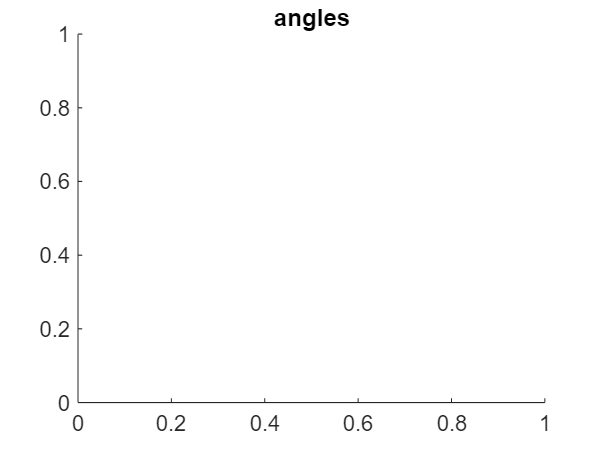

% Plot the results
figure;
title('angles')

plot(t_num_forced, z_forced(:, 3), yout{1}.Values.Time, yout{1}.Values.Data(:,3));

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

xlabel('Time (s)');
ylabel('$q_2$ (rad)', Interpreter='latex');
legend({'MATLAB', 'Simscape'})
grid on;

% Plot the results
figure;
title('velocities')
plot(t_num_forced, z_forced(:, 4), yout{1}.Values.Time, yout{1}.Values.Data(:,4));
xlabel('Time (s)');
ylabel('$\dot{q}_2$ (rad/s)',Interpreter='latex');
legend({'MATLAB', 'Simscape'})
grid on;